# LAB 3 Tylor Cooks 026538081

x_db = 0:0.1:14; % SNR EB/NO
x = 10.^(x_db/10); % db -> linear

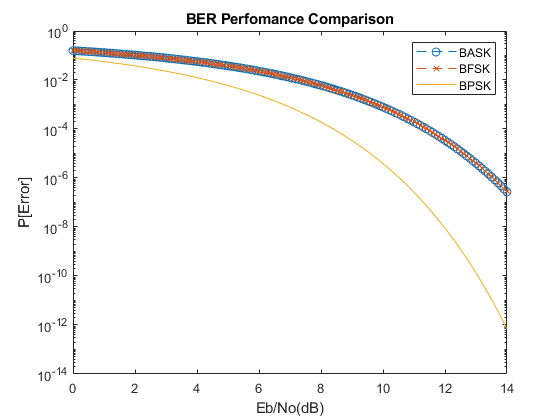

% avg power 
Q_BPSK_avg = qfunc(sqrt(2)*(sqrt(x)));
Q_BASK_avg = qfunc((sqrt(x)));
Q_BFSK_avg = qfunc(sqrt(x));
figure

semilogy(x_db,Q_BASK_avg,'--o','DisplayName','BASK');
hold on
semilogy(x_db,Q_BFSK_avg,'--x','DisplayName','BFSK');
semilogy(x_db,Q_BPSK_avg,'DisplayName','BPSK');
title('BER Perfomance Comparison')
ylabel('P[Error]')
xlabel('Eb/No(dB)')
hold off 
legend show

**[Discussion]**

    As seen in the "BER Performance Comparison" figure, there are 3 different modulation schemes being used, BASK, BFSK, and BPSK, with equally likely information bits "0" and "1". To compare error performances it is requred to express the error probablilites as the average energy per bit. As a result the BASK and BFSK have the same BER curve, even though they have a different modulation scheme. 

    The reason that the BASK and BFSK have the same BER performance is because of the relation between the distances between signal 1 and 2 and the boundary decision rule being in the middle between those two signals. 

**BASK Signal Set: **

The signal space plot will have the following representation:

However, if we want an accurate comparative BER performance


$$E_{\textrm{AVG}} =\frac{E_{\textrm{BASK}} }{2}\Rightarrow {2E}_{\textrm{AVG}} =E_{\textrm{BASK}}$$


Q function, substitute $E_{\textrm{AVG}}$ for $E_{\textrm{BASK}}$ : 

$Q\left(\frac{d}{\sqrt{{2N}_0 }}\right)$=> $Q\left(\frac{\sqrt{E_{\textrm{BASK}} }}{\sqrt{{2N}_0 }}\right)\Rightarrow Q\left(\frac{\sqrt{2E_{\textrm{AVG}} }}{\sqrt{2N_0 }}\right)=Q\left(\sqrt{\frac{E_{\textrm{AVG}} }{N_0 }}\right)$

The reason for the substitution is becase BASK boundery decision is in the middle between the two signals, so to compare the BER of different schemes , the average of the energy needs to be taken into account. 

**BFSK Signal Set: **

The signal space plot will have the following representation:

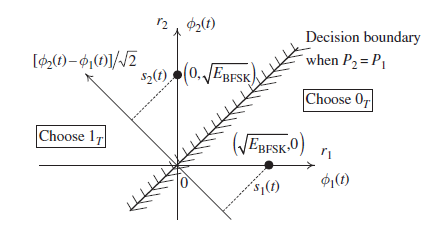

to find the distance between the two signals, use the simple pythagorean  theorem$a^2 +b^2 =c^2$, solving for c, which is the distance between both signals, $c=\sqrt{a^2 +b^2 }$.


$$c=\sqrt{E_{\textrm{BFSK}} +E_{\textrm{BFSK}} }=\sqrt{2E_{\textrm{BFSK}} }$$


Notice $\sqrt{2E_{\textrm{BFSK}} }$ = $\sqrt{2E_{\textrm{AVG}} }$


$$Q\left(\frac{d}{\sqrt{{2N}_0 }}\right)$$
 
$$\Rightarrow Q\left(\frac{\sqrt{2E_{\textrm{BFSK}} }}{\sqrt{2N_0 }}\right)\Rightarrow Q\left(\frac{\sqrt{2E_{\textrm{AVG}} }}{\sqrt{2N_0 }}\right)=Q\left(\sqrt{\frac{E_{\textrm{AVG}} }{N_0 }}\right)$$


**BPSK Signal Set: **

The signal space plot will have the following representation:


$$Q\left(\frac{d}{\sqrt{{2N}_0 }}\right)$$
 
$$\Rightarrow Q\left(\frac{2\sqrt{E_{\textrm{BFSK}} }}{\sqrt{2N_0 }}\right)\Rightarrow Q\left(\frac{\sqrt{4E_{\textrm{AVG}} }}{\sqrt{2N_0 }}\right)=Q\left(\sqrt{\frac{{2E}_{\textrm{AVG}} }{N_0 }}\right)$$


From the results in the theoretical and experimental results the BER performance of BASK and BFSK are equal, while the BPSK more effecient. 